# いろいろ練習用

A = 2 * rand(3,3) + 0.5

A =     0.6791    1.8076    1.0248
    1.8216    2.4068    2.2896
    2.3298    1.3803    2.1236



B = max(-2, min(2, A))

B =     0.6791    1.8076    1.0248
    1.8216    2.0000    2.0000
    2.0000    1.3803    2.0000


% syms x y
% fplot(hermiteH(0:4,x))
% axis([-2 2 -30 30])
% grid on
% 
% ylabel('H_n(x)')
% legend('H_0(x)', 'H_1(x)', 'H_2(x)', 'H_3(x)', 'H_4(x)', 'Location', 'Best')
% title('Hermite polynomials')


% t = 0:0.01:2*pi;
% x = sin(t);
% x = Data.X
% y0 = hermiteH(0, x);
% y1 = hermiteH(1, x);
% y2 = hermiteH(2, x);

% figure(1);
% subplot(3,1,1); plot(t, y0);
% subplot(3,1,2); plot(t, y1);
% subplot(3,1,1); plot(t, kron(y0,y1'));
% subplot(3,1,2); plot(t, kron(y1,y2'));
% subplot(3,1,3); plot(t, kron(y1,y0'));

% figure(2);
% subplot(3,1,1); plot(t, y2);

string(datetime('now'), 'yyyy-MM-dd_hh-mm-ss')

ans = "2024-09-24_06-38-24"

## 実機とシミュレーションの比較


clear; clc
N = 78

N = 78

exp = load(strcat('Exp_2_4_', num2str(N), '.mat'));
sim = load(strcat('HL_exp_', num2str(N), '.mat'));
edata_idx = find(exp.log.Data.phase == 102, 1, "first"):find(exp.log.Data.phase==102, 1, "last");
sdata_idx = find(sim.log.Data.phase == 102, 1, "first"):find(sim.log.Data.phase==102, 1, "last");
edata = cell2mat(arrayfun(@(N) exp.log.Data.agent.estimator.result{N}.state.get(),edata_idx,'UniformOutput',false));
sdata = cell2mat(arrayfun(@(N) sim.log.Data.agent.estimator.result{N}.state.get(),sdata_idx,'UniformOutput',false));
% reference xd(16,1) q(3,1) p(3,1) v(3,1)
eref = cell2mat(arrayfun(@(N) exp.log.Data.agent.reference.result{N}.state.get(),edata_idx,'UniformOutput',false));
sref = cell2mat(arrayfun(@(N) sim.log.Data.agent.reference.result{N}.state.get(),sdata_idx,'UniformOutput',false));
% time 
etime = exp.log.Data.t(edata_idx(end)+1)-exp.log.Data.t(edata_idx(1));
stime = sim.log.Data.t(sdata_idx(end))+0.025-sim.log.Data.t(sdata_idx(1));

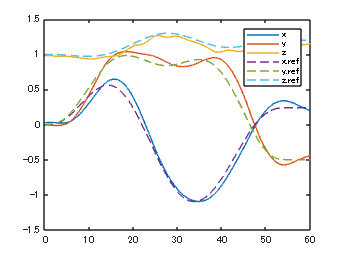

close all;
edata_t = linspace(0, stime(end), size(edata_idx,2));
sdata_t = linspace(0, stime(end), size(sdata_idx,2));
figure(1); ylabel('exp');
plot(edata_t, edata(1:3,:)); hold on;
plot(edata_t, eref(17:19,:), '--'); hold off;
legend("x","y","z","x.ref","y.ref","z.ref");

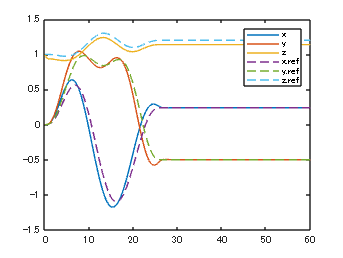

figure(2); ylabel('sim');
plot(sdata_t, sdata(1:3,:)); hold on;
plot(sdata_t, sref(17:19,:), '--'); hold off;
legend("x","y","z","x.ref","y.ref","z.ref");

% Data.tの変更



## clear


% T = zeros(150, 1);
% for i = 1:150
%     disp(i);
%     load(strcat('Exp_2_4_', num2str(i), '.mat'));
%     data_idx = find(log.Data.phase == 102, 1, "first"):find(log.Data.phase==102, 1, "last");
%     T(i) = log.Data.t(data_idx(end)+1)-log.Data.t(data_idx(1));
% end
% Tmax = max(T);


% close all
